# **Cam and Crank - Loopback **

This example demonstrates how to generate a Cam and Crank signal and how to decode the shaft position based on a pair of Cam and Crank signals. A pulse with a defined duration is generated at a specific angle using the Event module.

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file which supports** 1 x Cam and Crank Encoder v3 **channel (CRE) including** 1 x Event Capture **channel and** 1 x Cam and Crank Decoder v1 **channel including **1 x Event** channel.

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

- An oscilloscope to measure the generated signals (optional)

### Test Setup

The example is set up to generate a pair of Cam and Crank signals. Connect the Cam and Crank outputs to the corresponding inputs on the terminal board as indicated in the following pin wiring table. The exact pins depend on your specific configuration file. In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. The Crank decoder detects the position and speed of the Cam and Crank signals. 

The **Crank Decoder Event** module generates a pulse with a defined duration at a defined angle (event).The signal must be connected from the decoder to the encoder side on the terminal board. The angle at which the pulse occurs is detected by the **Crank Encoder Event Capture** module.

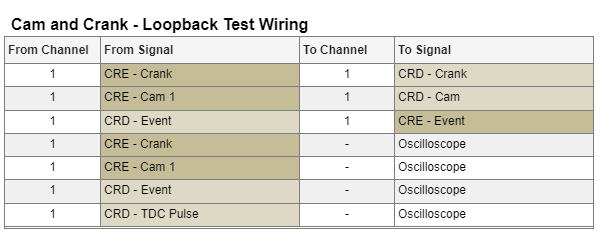

In addition to the loop back some of the signals are measured with an external oscilloscope for visualization according to the table.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_CamCrank_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

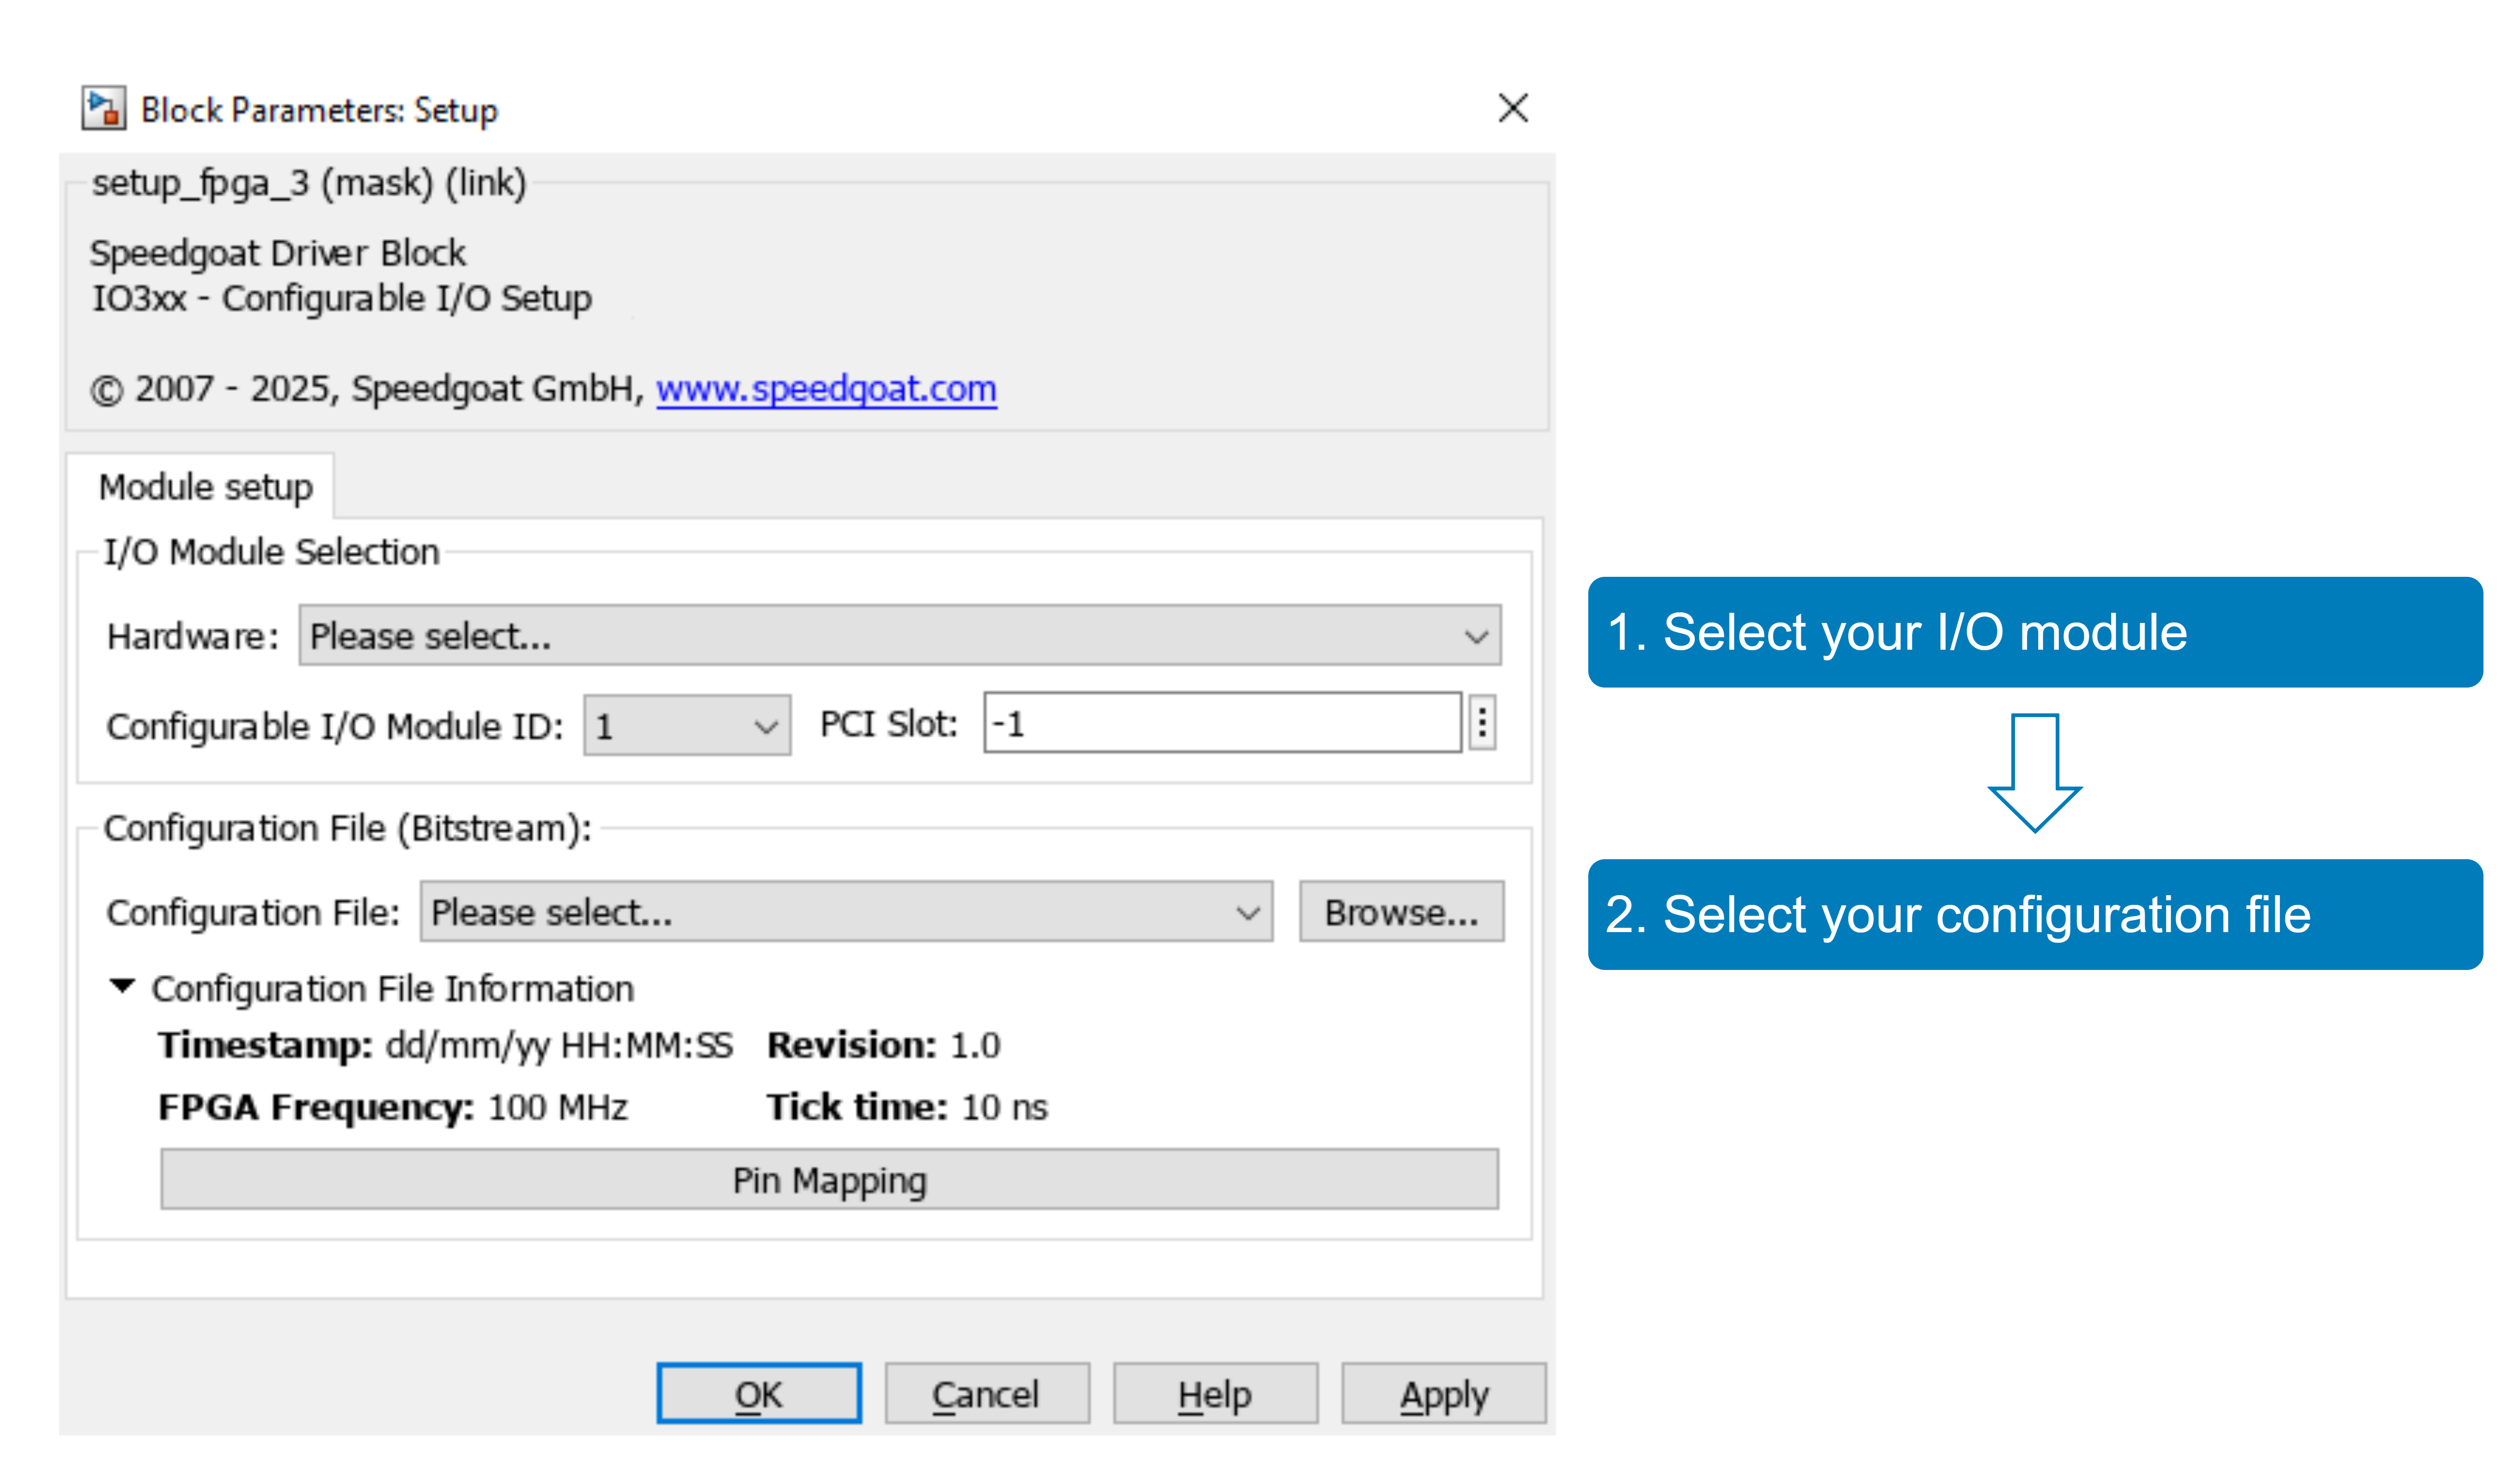

With the **Pin Mapping** button you can now check where the functionalities are located.

This model uses a sample time of 1 ms.

## Model Description 

### Crank Encoder

The model contains one instance of the Crank Encoder v3 block. The block is assigned to channel one and configured to generate a digital crank signal with 60 teeth (segments), of which two are missing teeth. The shaft speed is defined by the input signal to the **Speed** input.

### Cam Encoder

The Cam Encoder v3 block is configured to generate a digital cam signal with one pulse. The pulse occurs at 30 degrees and has a duration of 90 degrees. These values are defined in the **Initial Cam start matrix** and **Initial Cam length matrix **in the Cam Encoder tab of the block mask. The block is designed for a Cam signal with a maximum of 10 teeth and only accepts row vectors with 10 elements per channel. The Cam Encoder module inherits the position signal from the Crank Encoder module. This connection is programmed in the configuration file. Refer to the pin mapping of your configuration file to learn which Cam Encoder channels are linked to which Crank Encoder channels.

**Crank Encoder Event**

The Crank Encoder Event module is designed to measure the angle and duration of a pulse signal. The module is also hard wired to a Crank Encoder Channel from which it inherits the shaft position signal. This information is documented in the pin mapping of your configuration file and must be provided in the driver block mask (**Crank master channel**).

**Crank Decoder**

The Crank Decoder module can detect the shaft position based on a captured pair of Cam and Crank signals. The signal characteristics must be known and provided in the block mask (**Crank Decoder** tab). The following parameters must be known to decode the shaft position:

- Number of crank teeth

- Number of missing crank teeth

- Cam tooth position (in degrees)

- Cam tooth length (in degrees)

Note that the block only supports one cam tooth. The detected speed and position are fed into the Simulink model at the respective output ports.

The block also provides the possibility to generate a pulse signal with defined length at Top Dead Center (TDC) position of the shaft. The TDC angle can be defined in the block mask as well as the pulse duration in seconds. In addition, a pulse with user defined duration is generated every time the Cam shaft crosses the zero-degree position.

**Crank Decoder Event Capture**

The Crank Decoder Event module is linked to the Crank Decoder module on the FPGA. It is designed to generate a pulse signal based on the shaft position detected by the Crank Encoder module. Both position and duration of the pulse can be defined in the block mask.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model. Create the real-time application file
% (.mldatx).
slbuild(modelName);    

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

### Display Speed and Position

 
% Clear and set up the SDI view
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,2);

% Get the last run
allIDs = Simulink.sdi.getAllRunIDs;
lastRunID = allIDs(end);
lastRun = Simulink.sdi.getRun(lastRunID);

% Get the speed and position signals of both crank channels
SpeedRef = lastRun.getSignalsByName('Crank Encoder Speed');
Speed = lastRun.getSignalsByName('Crank Decoder Speed');
Position = lastRun.getSignalsByName('Crank Decoder Position');
PositionInterpolated = lastRun.getSignalsByName('Crank Decoder Position Interpolated');
Status = lastRun.getSignalsByName('Crank Decoder Sync Status');
EventStart = lastRun.getSignalsByName('Event Start');
EventLength = lastRun.getSignalsByName('Event Length');

% Display the speed and position of both crank channels
plotOnSubPlot(SpeedRef,1,1,true);
plotOnSubPlot(Speed,1,1,true);
plotOnSubPlot(Position,2,1,true);
plotOnSubPlot(PositionInterpolated,2,1,true);
plotOnSubPlot(Status,1,2,true);
plotOnSubPlot(EventStart,2,2,true);
plotOnSubPlot(EventLength,2,2,true);

% Set time range to see acceleration sequence between 0 and 2 seconds
Simulink.sdi.setSubplotLimits(1,1,'tRange',[0,2]);

% View SDI
Simulink.sdi.view;

You can see the acceleration of the crank shaft up to 600 rpm in SDI. The Crank decoder needs some cycles to fully synchronize to the received cam and crank signals. Full synchronization is achieved when the Crank Decoder Sync Status signal is four. This is the case when the decoder has detected the missing crank teeth and the cam tooth. Note that the output signals of the Crank Decoder module are invalid until the synchronization status reaches four. 

The decoder provides two position output signals. The raw position signal is incremented whenever the module detects a crank signal edge. The resolution of this signal depends on the number of crank teeth. The second position output provides an interpolated signal. The module interpolates the current position between two crank signal edges based on the current speed.

The **Crank Decoder Event** module generates a digital pulse when the detected position reaches 90 degrees. The pulse duration is set to 1 ms in the block mask. This pulse is detected by the **Crank Encoder Event Capture** module. In SDI you can see at which angle the pulse is detected and its length in degrees. The detected duration is 3.6 degrees which is equal to a duration of 1 ms at a speed of 600 rpm.

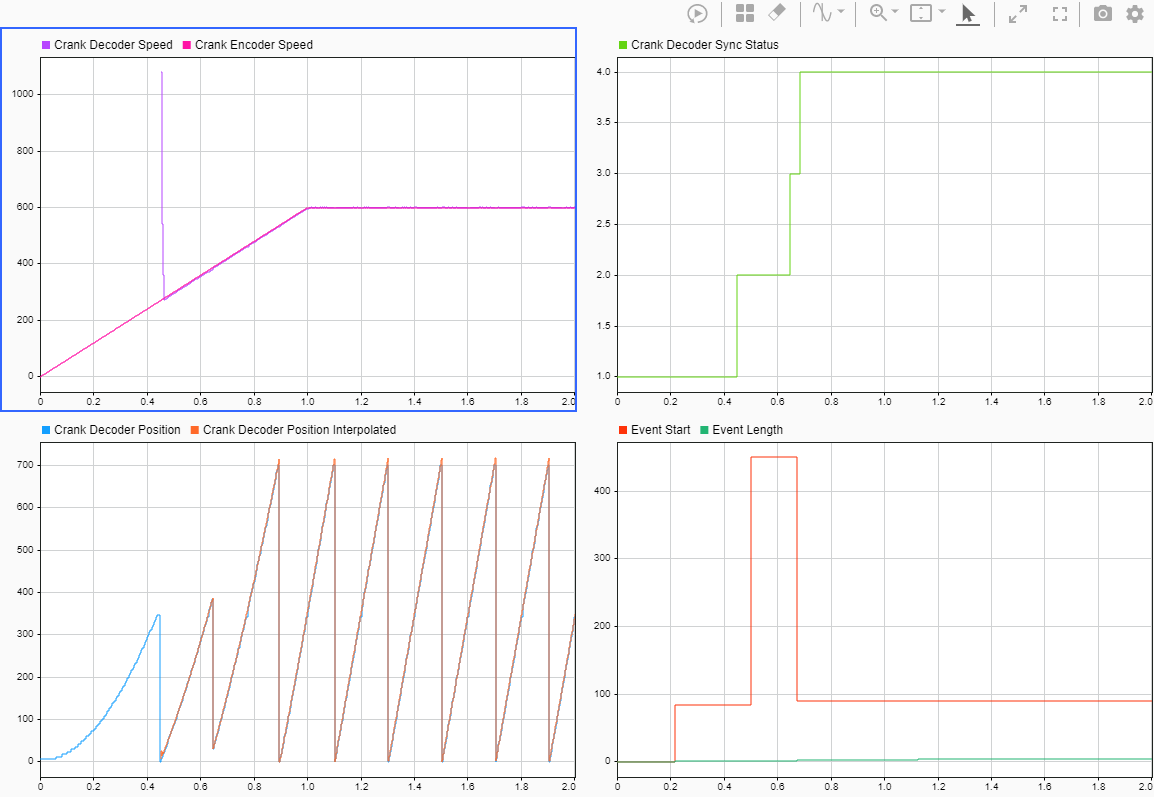

## Oscilloscope Measurements

The following figure shows the measured outputsignals on the oscilloscope.

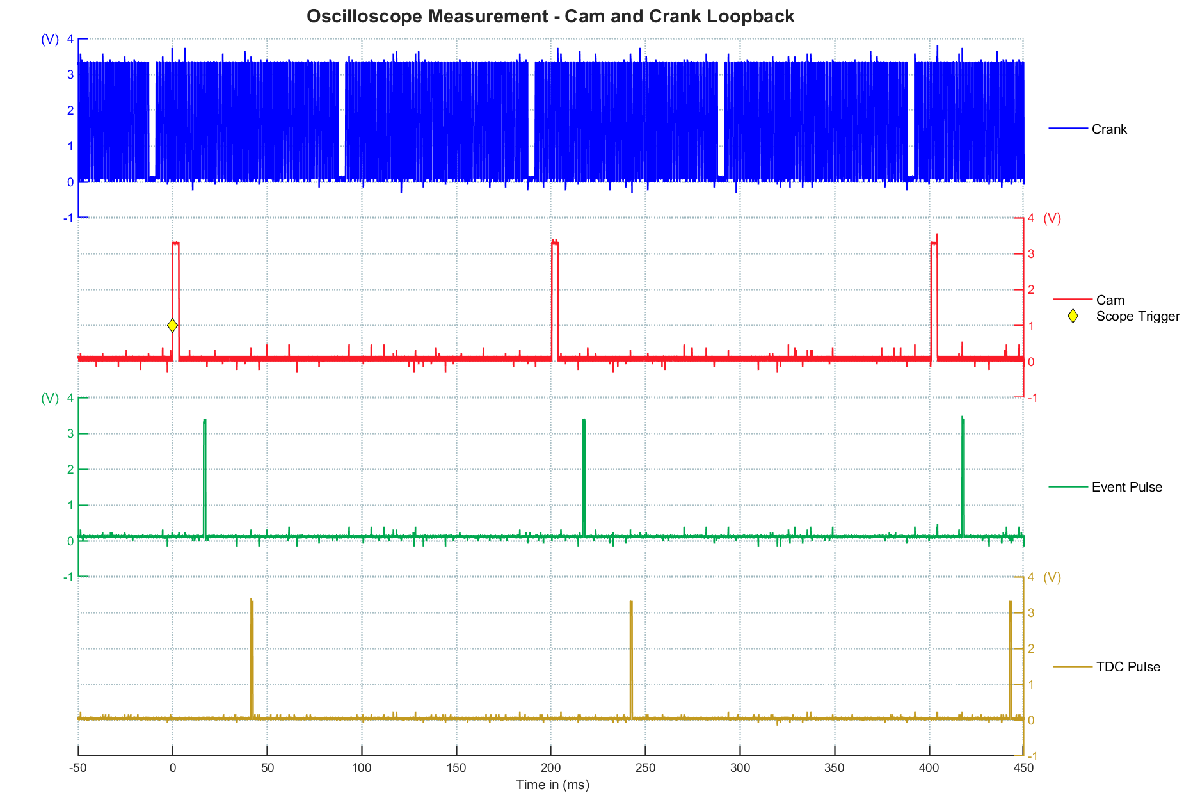

## Additional References

- [Cam and Crank documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_cam_and_crank)